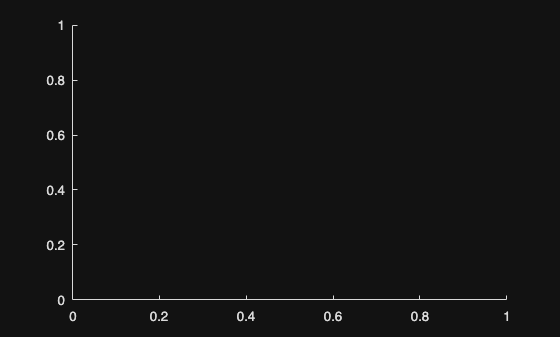

% run_a_star_3d_mapA.m  (works no matter where you run from)
clear; clc; close all;

% --- set your repo root ABSOLUTELY ---
repoRoot = '/Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning';  % <<— change if needed
assert(isfolder(repoRoot), 'Bad repoRoot: %s', repoRoot);

% --- paths ---
addpath(genpath(fullfile(repoRoot,'utils')));
addpath(genpath(fullfile(repoRoot,'global_planner')));

% --- load 3D map ---
mapFile = fullfile(repoRoot,'utils','data','map','mapA_20x30x30.mat'); % adjust name if different
assert(isfile(mapFile), 'Map not found: %s', mapFile);
S = load(mapFile);
grid_map = S.grid_map;

% --- plan with a_star_3d ---
start = [3, 2, 2];        % [row, col, z]
goal  = [18, 29, 25];
[path, flag, cost, expand] = a_star_3d(grid_map, start, goal);

% --- visualize ---
clf; hold on;

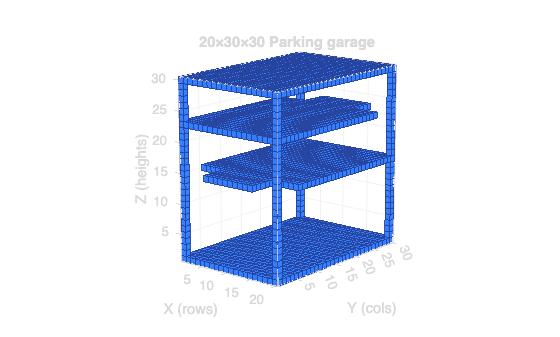

plot_grid_3d(grid_map);

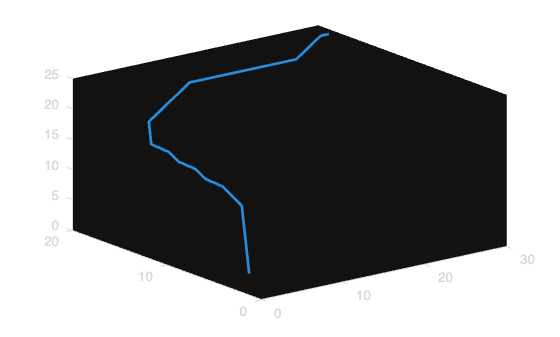

if ~isempty(path)
    plot3(path(:,2), path(:,1), path(:,3), '-', 'LineWidth', 2);
end

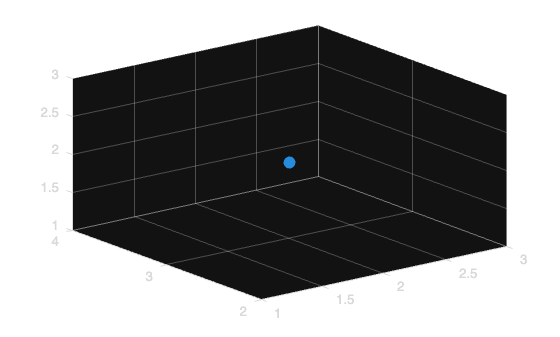

scatter3(start(2),start(1),start(3),80,'filled');

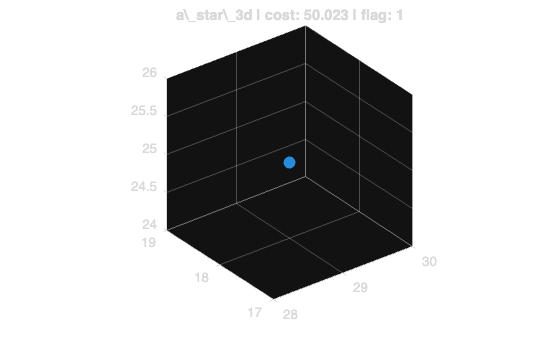

scatter3(goal(2),goal(1),goal(3),80,'filled');
title(sprintf('a\\_star\\_3d | cost: %.3f | flag: %d', cost, flag), 'Interpreter','none');
axis vis3d; grid on; view(3); hold off;